# Assignment 2

This file uses functions from the Signal Processing Toolbox.

## Loading an audio file to process

Add your own audio file to the same folder as this document is in.

clear variables;

% Load song
fname = 'song.wav';
[song, fs_song] = audioread(fname);

% Turn volume up/down
song = song.*0.2;

## Pole zero diagram to filter

Here is a short demonstration of how to take input in form of locations of poles and zeroes and turn them into a filter:

% The user input would look something like Z and P:
Z = [0.9*exp(i*pi/4); 0.9*exp(-i*pi/4)];
P = [0.5*exp(i*3*pi/4); 0.5*exp(-i*3*pi/4)];

% Uncomment to plot pole-zero diagram
%zplane(Z, P)

% Now find the polynomials with these poles and zeroes as their roots
B1 = poly(Z);
A1 = poly(P);

% Uncomment to take a look at the frequency response
%freqz(B1, A1)

% Now filter the audio from the input file
song_PZFilter = filter(B1, A1, song);

% Uncomment to listen to song before and after the filter
% Write "clear sound" in the console to stop the playback
%sound(song, fs_song)           % Before
%sound(song_PZFilter, fs_song)  % After

## 12-Band equaliser

Here, an array of 12 values get taken as user input and used to make an equaliser:

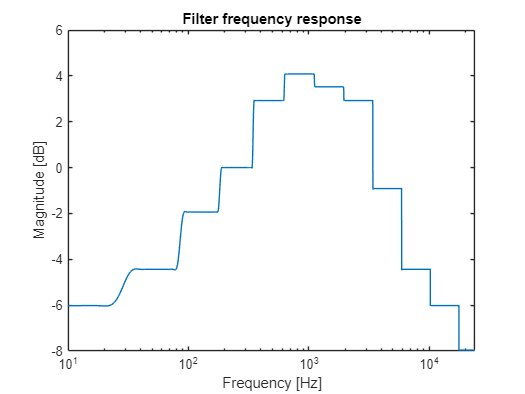

% Input array from user:
eq_array = [0.5, 0.6, 0.8, 1.0, 1.4, 1.6, 1.5, 1.4, 0.9, 0.6, 0.5, 0.4];

% Creating the desired frequency response:
spacing = (logspace(log10(20), log10(fs_song/2), 14)')./2;
eq_fr = ones(1,round(spacing(2)-spacing(1))).*eq_array(1);
for idx = 2:12
    eq_fr = [eq_fr ones(1,round(spacing(idx+1)-spacing(idx))).*eq_array(idx)];
end

% Mirror it to get symmetry
eq_fr = [eq_fr zeros(1,round(spacing(13+1)-spacing(12))) fliplr(eq_fr)];
%stem(eq_fr)

% Find IR, remove imaginary parts and "clean edges" with a hann window:
eq_IR = ifftshift(ifft(eq_fr, round(length(eq_fr)/2), 'symmetric'));
eq_IR = eq_IR.*(hann(round(length(eq_fr)/2))');
%plot(eq_IR)

% Filter frequency response:
% Get coefficients from IR for plotting
[amp, freq_vec] = freqz(eq_IR,1,length(eq_fr), fs_song, fs_song);
figure(1)
semilogx(freq_vec, 20*log10(abs(amp)))
xlabel('Frequency [Hz]');
ylabel('Magnitude [dB]');
title('Filter frequency response');
xlim([10, fs_song/2]);


% Filtering the audio from the input file (NOTE: This can take a while)
%song_12BandEQ = filter(eq_IR, 1, song);

% Uncomment to listen to song before and after the filter
% Write "clear sound" in the console to stop the playback
%sound(song, fs_song)           % Before
%sound(song_12BandEQ, fs_song)  % After

## *Echo*

### *Echo*

***Echo***

This part takes two inputs from the user: How long the delay should be, and how loud the echo should be.

% User inputs
delay = 250;    % in ms
loudness = 0.4; % should be in the range 0 <= loudness < 1

% Convert delay in time to delay in samples
delaySamples = ceil((fs_song/1000) * delay);

% Set filter coefficients
B2 = 1;
A2 = [1 zeros(1, delaySamples-1) loudness*(-1)];

% Have a quick look at the impulse response
%impz(B2, A2)

% Process the sound with the filter
%song_echo = filter(B2, A2, song);

% Uncomment to listen to song before and after the filter
% Write "clear sound" in the console to stop the playback
%sound(song, fs_song)       % Before
%sound(song_echo, fs_song)  % After